**Estimating matrix-valued covariance function:**

$Cov[V](s,t)= \left[\matrix{ Cov_{1,1}(s,t) & \cdots & Cov_{1,d}(s,t) \cr \vdots & & \vdots  \cr Cov_{d,1}(s,t) & \cdots & Cov_{d,d}(s,t)}  \right]$ & $Cor[V](s,t)= \left[\matrix{ Cor_{1,1}(s,t) & \cdots & Cor_{1,d}(s,t) \cr \vdots & & \vdots  \cr Cor_{d,1}(s,t) & \cdots & Cor_{d,d}(s,t)}  \right]$

**Import data**

The data is stored in the table `mortality_rates and mortality_rates_array`. The first two columns are Year and Age, and the remaining 47 columns are death rates for different prefectures (e.g. Tokyo).

load('Data\mortality_rates.mat')
load('Data\mortality_rates_array.mat')

**Estimate Covariance**

Here, our estimators are

$\hat{Cov}_{i,j}(s,t) = N^{-1}\sum_{k=1}^{N}(v_i(s)-\hat{\mu}_i(s))(v_j(t)-\hat{\mu}_j(t))$,


$$\hat{Cor}_{i,j}(s,t) = \frac{N^{-1}\sum_{k=1}^{N}(v_i(s)-\hat{\mu}_i(s))(v_j(t)-\hat{\mu}_j(t))}{s_i(s) s_j(t)$$


with

$\hat{\mu}_i(s) = N^{-1}\sum_{k=1}^{N}v_i(s)$, $s_i(x) = (N-1)^{-1}\sum_{i=1}^{n}(v_i(x)-\hat{\mu}(x))^2$.

Here, we consider the situation where $v$ is a 

m00 = correlation_matrix(0,0,mortality_rates_array)

nages = 96

nprefectures = 47

nyears = 45

m00 =     0.9778    0.8732    0.9178    0.9365    0.9060    0.8382    0.9183    0.9263    0.9229    0.9179    0.9273    0.9366    0.9264    0.9031    0.8714    0.8741    0.8802    0.8981    0.9376    0.8541    0.9000    0.8993    0.8874    0.8814    0.9087    0.9231    0.8774    0.8789    0.9142    0.8923    0.8794    0.8952    0.9422    0.8812    0.9353    0.9197    0.8343    0.9238    0.9000    0.7635    0.9361    0.7666    0.8915    0.8995    0.8498    0.8757    0.8268
    0.8732    0.9778    0.8647    0.8829    0.8118    0.7608    0.8427    0.8613    0.8681    0.8784    0.8867    0.8782    0.8354    0.8616    0.8013    0.8382    0.8328    0.8768    0.8609    0.7652    0.8705    0.8020    0.8260    0.8664    0.7927    0.8319    0.8755    0.8003    0.8382    0.8307    0.8070    0.8167    0.8676    0.8189    0.8559    0.8194    0.7406    0.8846    0.8243    0.7663    0.8592    0.7552    0.8219    0.8401    0.7580    0.8337    0.7930
    0.9178    0.8647    0.9778    0.9089    0.8445  

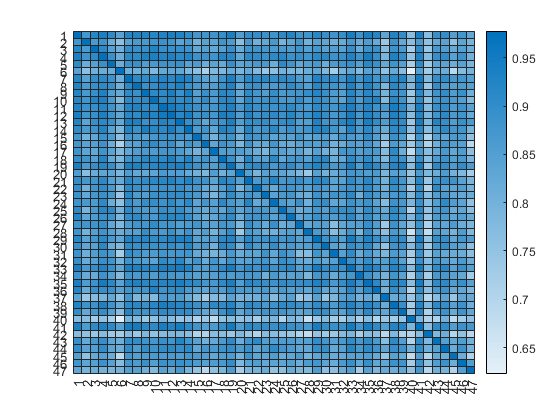

heatmap(m00)


m00 = correlation_matrix(0,0,mortality_rates_array)

nages = 96

nprefectures = 47

nyears = 45

m00 =     0.9778    0.8732    0.9178    0.9365    0.9060    0.8382    0.9183    0.9263    0.9229    0.9179    0.9273    0.9366    0.9264    0.9031    0.8714    0.8741    0.8802    0.8981    0.9376    0.8541    0.9000    0.8993    0.8874    0.8814    0.9087    0.9231    0.8774    0.8789    0.9142    0.8923    0.8794    0.8952    0.9422    0.8812    0.9353    0.9197    0.8343    0.9238    0.9000    0.7635    0.9361    0.7666    0.8915    0.8995    0.8498    0.8757    0.8268
    0.8732    0.9778    0.8647    0.8829    0.8118    0.7608    0.8427    0.8613    0.8681    0.8784    0.8867    0.8782    0.8354    0.8616    0.8013    0.8382    0.8328    0.8768    0.8609    0.7652    0.8705    0.8020    0.8260    0.8664    0.7927    0.8319    0.8755    0.8003    0.8382    0.8307    0.8070    0.8167    0.8676    0.8189    0.8559    0.8194    0.7406    0.8846    0.8243    0.7663    0.8592    0.7552    0.8219    0.8401    0.7580    0.8337    0.7930
    0.9178    0.8647    0.9778    0.9089    0.8445  

heatmap(m00)

function [m] = correlation_matrix(age1,age2,mortality_rates_array)

[nages,nprefectures,nyears] = size(mortality_rates_array)


m = zeros(nprefectures);

for j = 1:nprefectures
    for k = 1:nprefectures
        m(j,k) = fast_fcor(age1,age2,j,k,nyears,mortality_rates_array);
    end
end



end

function [c] = fcov(s,t,i,j,N,mortality_rates)

year = unique(mortality_rates.Year);

vi = zeros(N,1);
vj = zeros(N,1);
    
    for yr = 1:length(year)
       
        vi(yr) = characteristic_function(s,mortality_rates{:,i+2}(mortality_rates.Year == year(yr)), ...
            mortality_rates{mortality_rates.Year == year(yr), i+2});
       
        vj(yr) = characteristic_function(t,mortality_rates{:,j+2}(mortality_rates.Year == year(yr)), ...
            mortality_rates{mortality_rates.Year == year(yr), j+2});
        
    end
    
    c = 1/N*dot(vi-mean(vi),vj-mean(vj));
    

end

%%% Correlation function ------------------------------------
function [c] = fcor(s,t,i,j,N,mortality_rates)

year = unique(mortality_rates.Year);

vi = zeros(N,1);
vj = zeros(N,1);
    
    for yr = 1:length(year)
       
        vi(yr) = characteristic_function(s,0:95, ...
            mortality_rates{mortality_rates.Year == year(yr), i+2});
       
        vj(yr) = characteristic_function(t,0:95, ...
            mortality_rates{mortality_rates.Year == year(yr), j+2});
        
    end
    
    c = 1/N*dot(vi-mean(vi),vj-mean(vj))/(std(vi)*std(vj));
    

end

function [c] = fast_fcor(s,t,i,j,N,mortality_rates_array)

       
        vi = mortality_rates_array(s+1,i,:);       
        vj = mortality_rates_array(t+1,j,:);        

    c = 1/N*dot(vi-mean(vi),vj-mean(vj))/(std(vi)*std(vj));
    
end